# Example: Fitter FSAE TTC

This example interactively guides you through fitting and exporting a magic formula tire model to measurement data acquired from the [FSAE Tire Test Consortium (TTC)](https://www.fsaettc.org/). The process would be similar with data from other sources, but the user would have to write their own parser (input data --> `tydex.Measurement`).

clear

## 1 Import measurement data

FSAE TTC usually tests either

- Drive / Brake (Varying but steady-state slip angle, then slip ratio sweeps)

- Cornering (No slip ratio, but slip angle sweeps)

folder = fileparts(matlab.desktop.editor.getActiveFilename());
folder = fullfile(folder, 'fsae-ttc-data');
fileDriveBrake = fullfile(folder, 'fsaettc_obscured_testbench_drivebrake.mat');
fileCornering = fullfile(folder, 'fsaettc_obscured_testbench_cornering.mat');
parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurementsDriveBrake = parser.run(fileDriveBrake);
measurementsCornering = parser.run(fileCornering);

Downsample data for quicker fitting:

measurements = [measurementsDriveBrake measurementsCornering];
measurementsDownsampled = measurements.downsample(50, 0);

## 2 Fit the tire model

Select modes to fit:

fitmodes = {'Fx0','Fy0','Mz0','Fx','Fy','Mz','Mx'};

Create tire model:

tyre = MagicFormulaTyre();

General model parameters:

tyre.Parameters.NOMPRES.Value = measurements(1).NOMPRES;
tyre.Parameters.FNOMIN.Value = measurements(1).FNOMIN;
tyre.Parameters.UNLOADED_RADIUS.Value = 0.2025;

Set other constraints of your choosing:

tyre.Parameters.PCY1.Value = 2;
tyre.Parameters.PCY1.Fixed = true;

Fit model:

options = optimoptions('fmincon', 'Display', 'iter-detailed', 'UseParallel', true);
tyre.fit(measurementsDownsampled, fitmodes, options)

Fitting Fx0...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 10).
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      20    4.047952e+08    0.000e+00    2.219e+08
    1      46    3.243787e+08    0.000e+00    3.110e+09    9.942e-01
    2      67    3.192831e+08    0.000e+00    3.125e+09    2.179e+00
    3      90    2.932452e+08    0.000e+00    3.079e+09    5.036e+00
    4     111    1.569219e+08    0.000e+00    2.863e+09    1.363e+01
    5     131    1.293351e+08    0.000e+00    1.471e+09    1.112e+01
    6     153    1.249843e+08    0.000e+00    3.934e+08    1.042e+01
    7     178    8.036067e+07    0.000e+00    1.753e+09    2.542e+00
    8     199    7.757546e+07    0.000e+00    1.310e+09    3.274e+00
    9     219    6.570613e+07    0.000e+00    1.257e+09    1.940e+01
   10     239    5.523899e+07    0.000e+00    1.455

## 3 Verify model-data fit

Select some measurement to compare to.

selection1 = [50 75 97 105 120];
selection2 = [15 30 35 40 45];

If the model fit is not satisfactory, try altering the min/max settings above or the initial values.

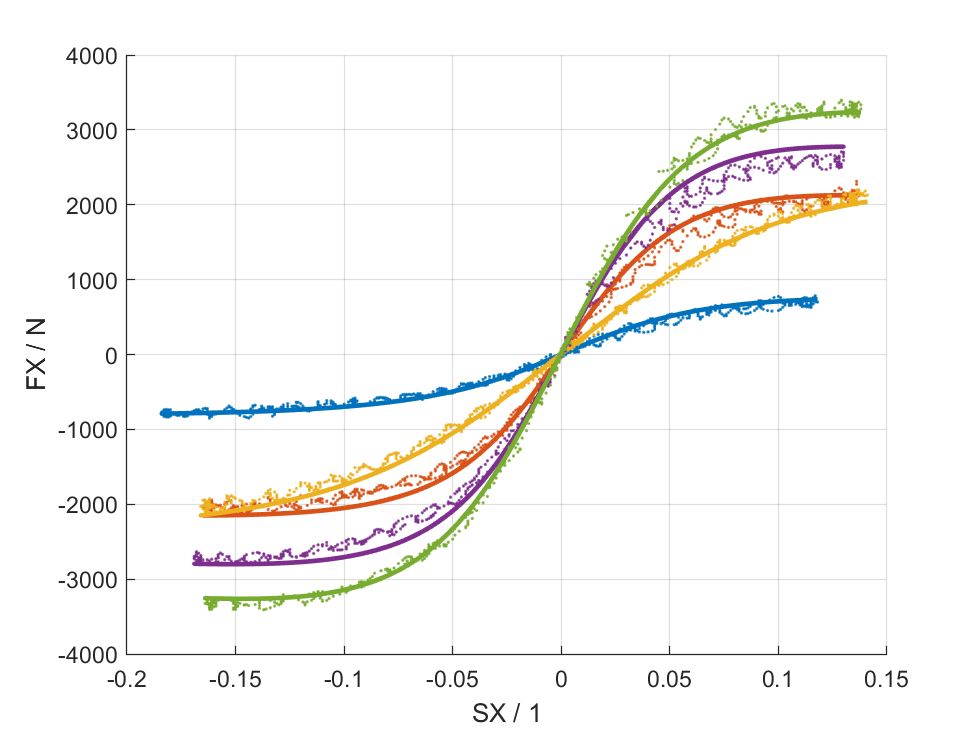

figure(); grid on; hold on
measurements = measurementsDriveBrake(selection1);
magicformula.plots.compareFxSX(tyre, measurements)

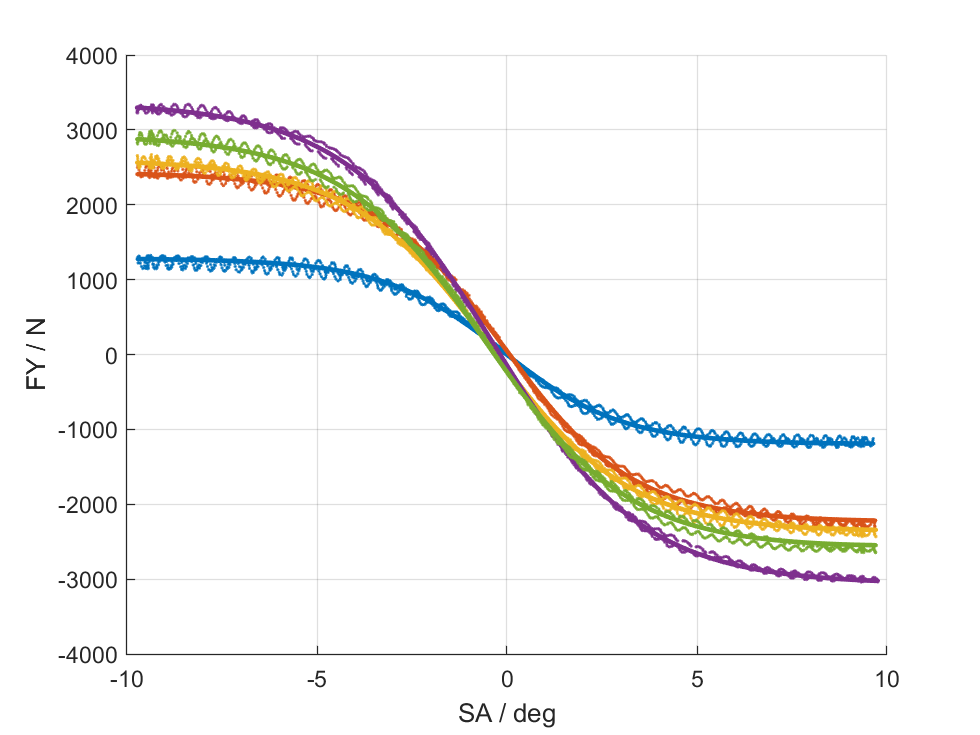

figure(); grid on; hold on
measurements = measurementsCornering(selection2);
magicformula.plots.compareFySA(tyre, measurements)

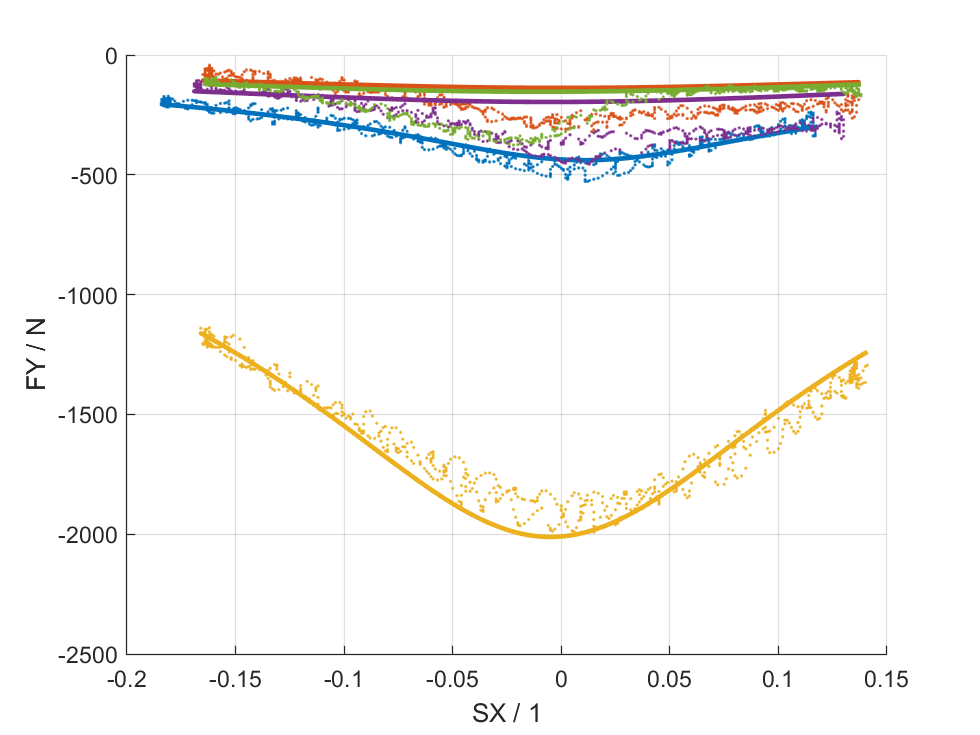

figure(); grid on; hold on
measurements = measurementsDriveBrake(selection1);
magicformula.plots.compareFySX(tyre, measurements)

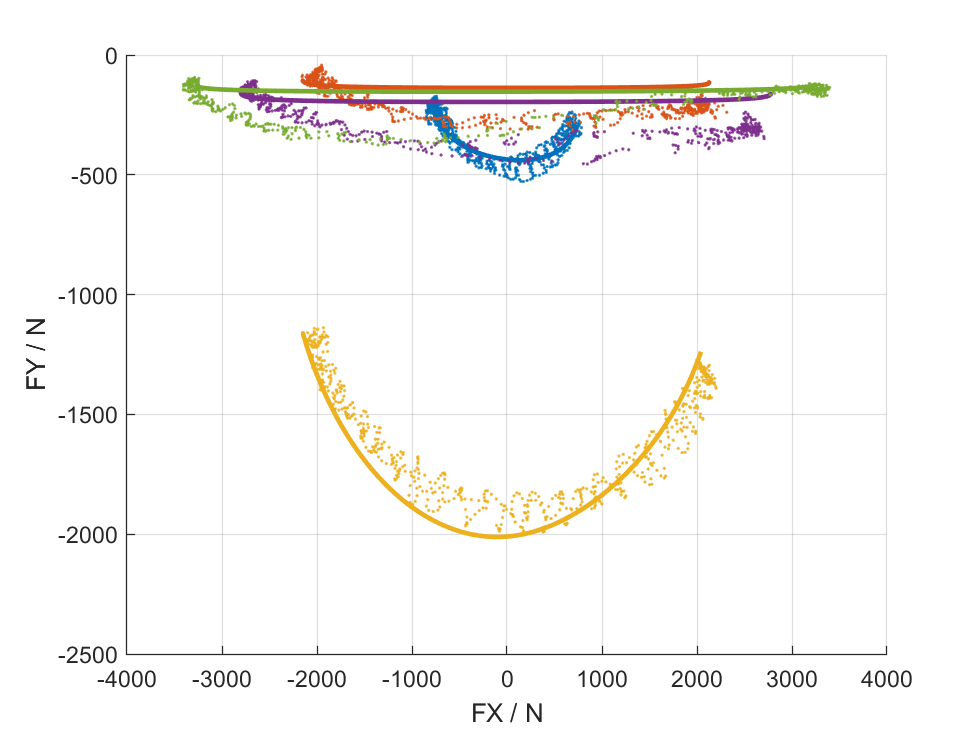

figure(); grid on; hold on
measurements = measurementsDriveBrake(selection1);
magicformula.plots.compareFxFy(tyre, measurements)

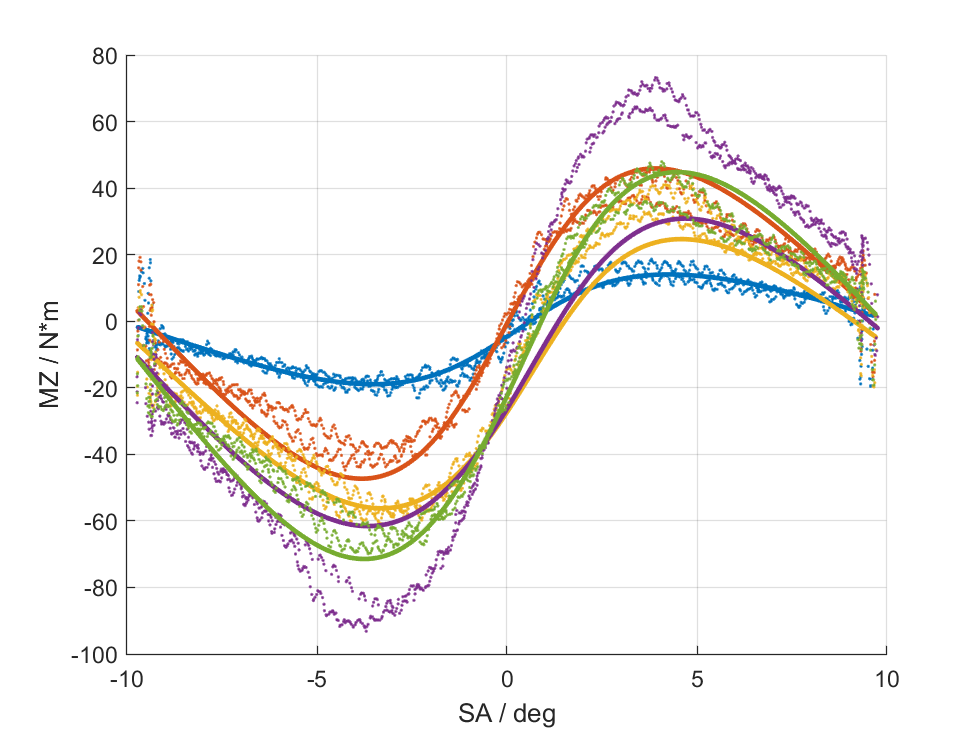

figure(); grid on; hold on
measurements = measurementsCornering(selection2);
magicformula.plots.compareMzSA(tyre, measurements)

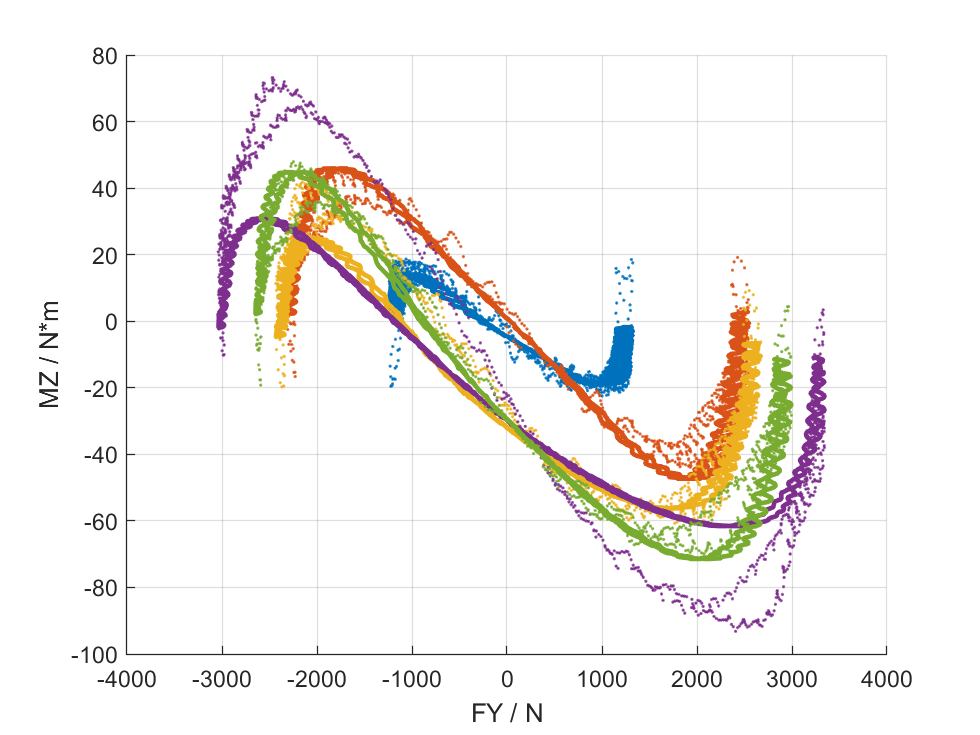

figure(); grid on; hold on
measurements = measurementsCornering(selection2);
magicformula.plots.compareMzFy(tyre, measurements)

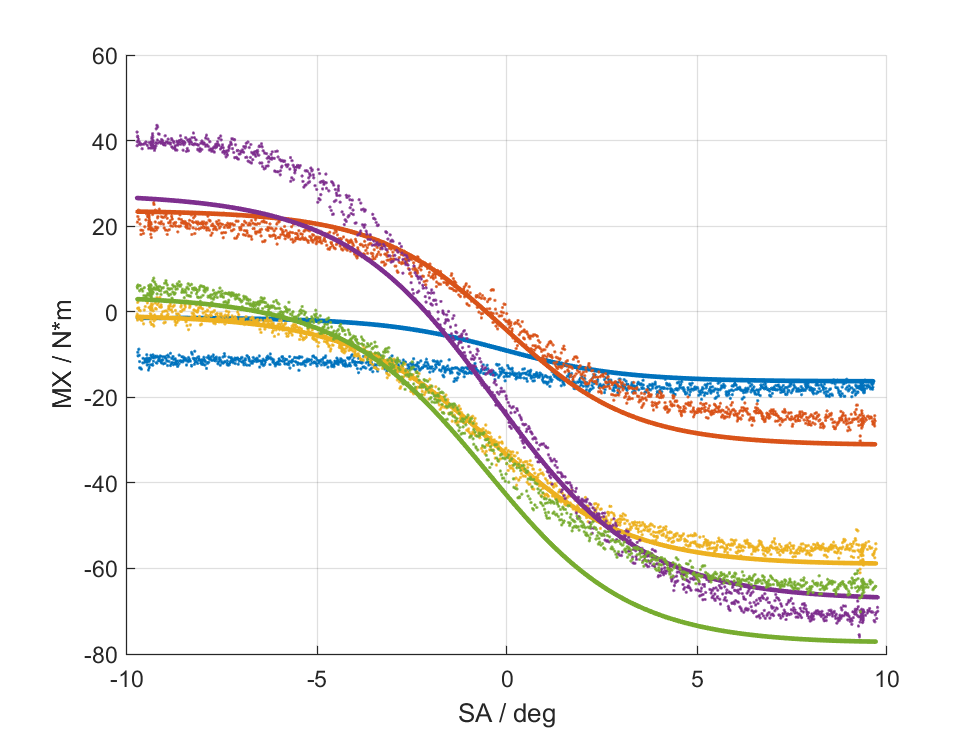

figure(); grid on; hold on
measurements = measurementsCornering(selection2);
magicformula.plots.compareMxSA(tyre, measurements)

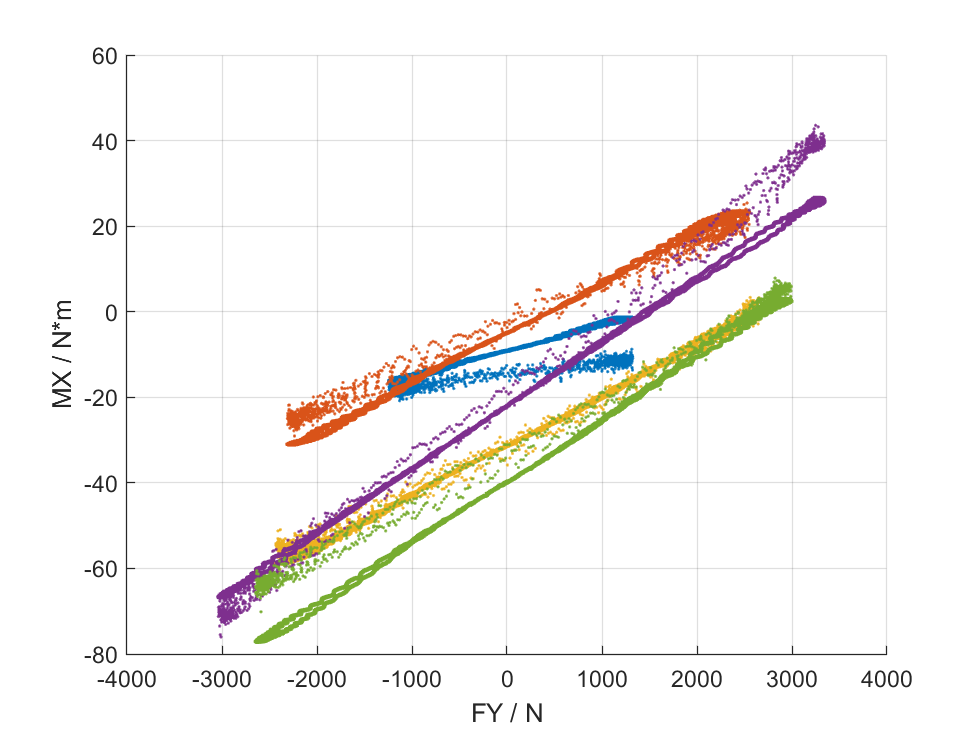

figure(); grid on; hold on
measurements = measurementsCornering(selection2);
magicformula.plots.compareMxFy(tyre, measurements)

## 4 Export fitted model

Export as Tyre Property File (.tir)

file = [tempname() '.tir'];
tyre.saveTIR(file, 'DisplayConsole', false)
winopen(file)

Export as Struct and save to MAT

params = struct(tyre.Parameters);
save('Example.mat', '-struct', 'params')

## 5 Store Fitting Settings

savefile = fullfile(tempdir(), 'test.md');
tyre.Parameters.saveFittingSettings(savefile)
disp(readlines(savefile))

    "| Parameter            | Min                  | Max                  | Fixed                |"
    "| -------------------- | -------------------- | -------------------- | -------------------- |"
    "| PCX1                 | 1.500000E+00         | Inf                  | false                |"
    "| PCY1                 | 1.500000E+00         | 5.000000E+00         | true                 |"
    "| PDX1                 | 1.000000E+00         | 5.000000E+00         | false                |"
    "| PDX2                 | -1.000000E+00        | 0.000000E+00         | false                |"
    "| PDX3                 | 0.000000E+00         | 1.500000E+01         | false                |"
    "| PDXP1                | -Inf                 | Inf                  | false                |"
    "| PDXP2                | -Inf                 | Inf                  | false                |"
    "| PDXP3                | -Inf                 | Inf                  | false                |"
